Remove Excess Figures

clc
clear
close all

Variable Initialization

global n
global L
P = 400/6;

n = 1000; % Number of locations to evaluate bridge failure
L = 1250; % Length of bridge
x = linspace(0, L, n); % Define x coordinate
SFD_PL = zeros(1, n); % Initialize SFD(x)


Sectional Properties

% There are many (more elegant ways) to construct cross-section objects
xc = [550 1060 L]; % Location, x, of cross-section change
bft = [100 100 100]; % Top Flange Width
tft = [1.27 1.27 1.27]; % Top Flange Thickness
hw = [72.46 72.46 72.46]; % Web Height
tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
dw = [78.73 78.73 78.73];
bfb = [80 80 80]; % Bottom Flange Width
tfb = [1.27 1.27 1.27]; % Bottom Flange Thickness
a = [550 510 190]; % Diaphragm Spacing
ac = [550, 1060, 1250]; %Diaphragm Locations
h = tft + tfb + hw; %total height
yglue = [73.73 73.73 73.73]; %location of glue joint to
ttg = [10 10 10]; %thickness of glue tab


%{xc, bft, tft, hw, tw, bfb, tfb, a}

% Optional but you need to ensure that your geometric inputs are correctly implemented
%VisualizeBridge( {CrossSectionInputs} );



Material Properties

SigT = 30;
SigC = 6;
E = 4000;
TauU = 4;
TauG = 2;
mu = 0.2;



Point Load Analysis

Train at right end

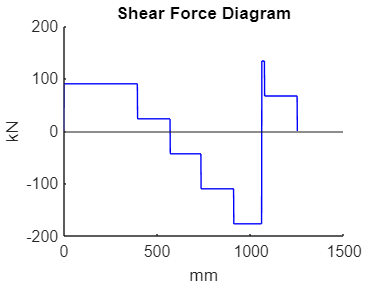

wheel_point = [394, 570, 734, 910, 1074, 1250]; % train in middle of the bridge
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(1), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(2), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(3), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(4), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(5), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(6), (400/6), x, SFD_PL);
    %wheel_point = wheel_point + i;

    figure(1)
    hold on
    plot(x, SFD_PL, "b")
    title('Shear Force Diagram')
    ylabel('kN')
    xlabel('mm')
    xline(0)
    yline(0)
    hold off

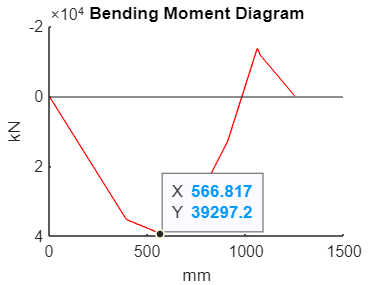


    figure(2)
    hold on
    plot(x, BMD_PL, "r")
    title('Bending Moment Diagram')
    ylabel('kN')
    xlabel('mm')
    set(gca, 'YDir','reverse')
    xline(0)
    yline(0)
    hold off



% below is my code to graph the BMD and SFD

Call Functions

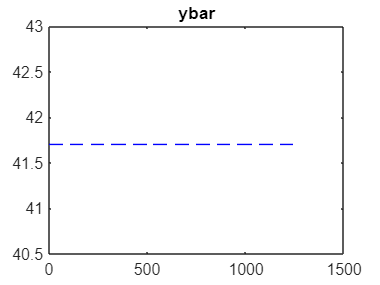

[ ybar, I, Q, Q_glue] = SectionProperties( xc, bft, tft, hw, tw, bfb, tfb);
plot(x, ybar, 'b--')
title('ybar')

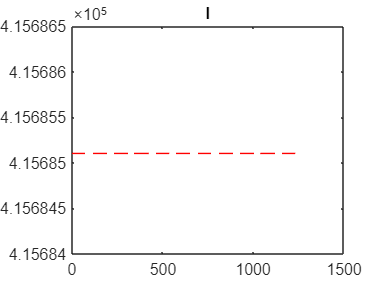


plot(x, I, 'r--')
title('I')

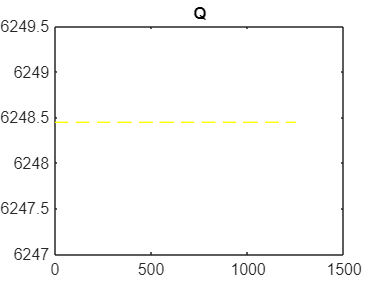


plot(x, Q, 'y--')
title('Q') 

V_Mat = Vfail( ybar, I, Q, xc, tfb, bfb, hw, bft, tw, TauU, 0, ttg);
V_Glue = Vfail( ybar, I, Q_glue, xc, tfb, bfb, hw, bft, tw, TauG, 1, ttg);
V_Buck = VfailBuck(a, tw, hw, I, Q, E, mu, xc, ac);
M_MatT = MfailMatT(I, ybar, h, SigT, BMD_PL, xc);
M_MatC = MfailMatC(I, ybar, h, SigC, BMD_PL, xc);
M_Buck1 = MfailBuck(tw, tft, bft, tfb, bfb, hw, E, I, mu, BMD_PL, 1, xc, ybar, dw);
M_Buck2 = MfailBuck(tw, tft, bft, tfb, bfb, hw, E, I, mu, BMD_PL, 2, xc, ybar, dw);
M_Buck3 = MfailBuck(tw, tft, bft, tfb, bfb, hw, E, I, mu, BMD_PL, 3, xc, ybar, dw);
Pf = FailLoad( P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3 )

ans =     3.8218   22.6642    5.1307    7.6042    1.9046    1.1323    6.5931   10.6694


Pf = 75.4853

% deflection = deflection(x, BMD_PL, I, E)


